# 3. Different SVM Models

This live script is intended as supplementary material for section 3 of the report. For this live script, we will create a small dataset on which to test our Support Vector Machine models, and compare our four methods on this small dataset. In order to run this script, you will need to have installed both the MOSEK optimisation package for MATLAB, as well as the YALMIP interface. For full details on formulations and meanings of variables and terms, please see Section 3 of the report.

### Dataset

For easy visualisation, we will consider $m=16$ data points, with only $n=2$ features. The first class of points (labelled as $+1$) will be lie within a square of size $2$ centred around the point $\left(2,2\right)$, whereas the second class of points (labelled as $-1$) will lie within a square of size $2$ centred at $\left(3,3\right)$. 

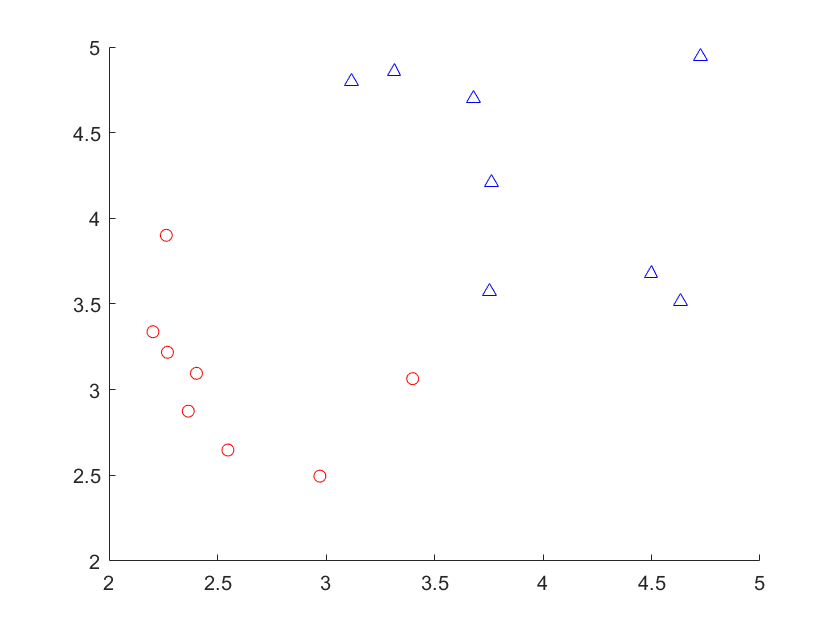

format short

x = [2*rand(8,2) + 2;
     2*rand(8,2) + 3];
y = [ones(8,1);
    -ones(8,1)];

scatter(x(1:8,1),x(1:8,2),'ro')
hold on
scatter(x(9:end,1),x(9:end,2),'b^')
hold off

As we can see, this data is **not **linearly separable, and so our soft-margin models are required.

### Model 1: Standard SVM

The standard SVM is formulated as a quadratic program in dual form:


$${\mathrm{min}}_u \;\;\frac{1}{2}{u^T \mathit{YXX}}^T Y^T u-e^T u\;\;\;\;\mathrm{subject}\;\mathrm{to}\;\;\;\;e^T Y^T u=0,\;\;\;\;0\le u\le \lambda \;e$$


Below we create a function that takes as input, the data points $x$, their classification $y$ and the regularization parameter $\lambda \;$, then solves the above optimisation problem, and returns the weights $w$ and the bias $\gamma \;$, as well as an array $\mathit{sv}$ of indices that indicate the support vectors. 

[w, gamma, sv] = standard_svm(x,y,0.8) 

w =    -0.9955
   -1.0955


gamma = -7.3572

sv =     10    13


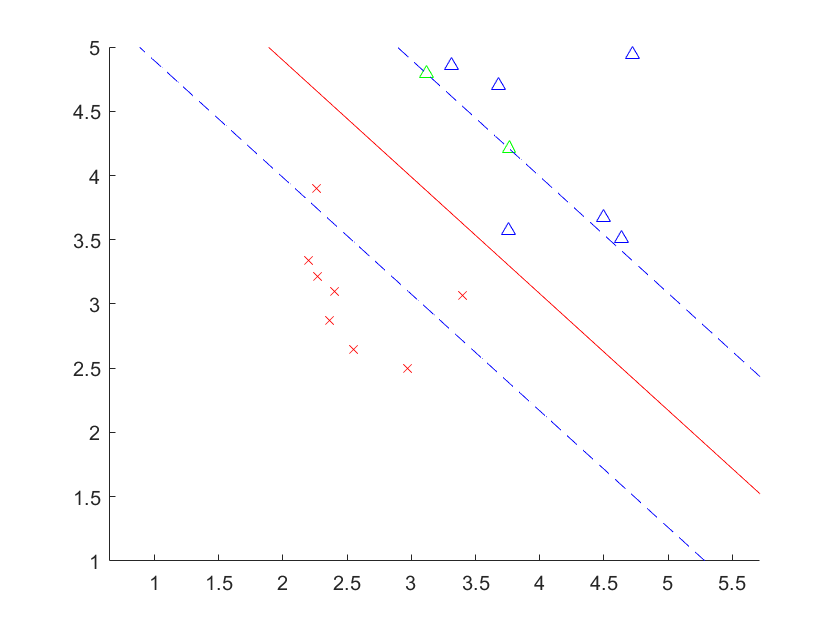

visualise(m,x,y,w,gamma,sv)

### Model 2: $L_{1\;} -$SVM

The $L_1$SVM is formulated and solved via a $\mathit{pq}$ substitution, which turns it into a linear program:


$${\mathrm{min}}_{p,q,\gamma ,\xi \;} e_n^T \left(p+q\right)+\lambda \;e_m^T \xi \;\;\;\;\mathrm{subject}\;\mathrm{to}\;\;\;\;Y\left(X\left(p-q\right)-e_m \gamma \;\right)+\xi \ge e_m ,\;\;\;\;p,q,\xi \ge 0$$
 

[w, gamma, sv] = l1_svm(x,y,0.8)

w =    -1.0882
   -1.1976


gamma = -8.1355

sv =      2    10    13


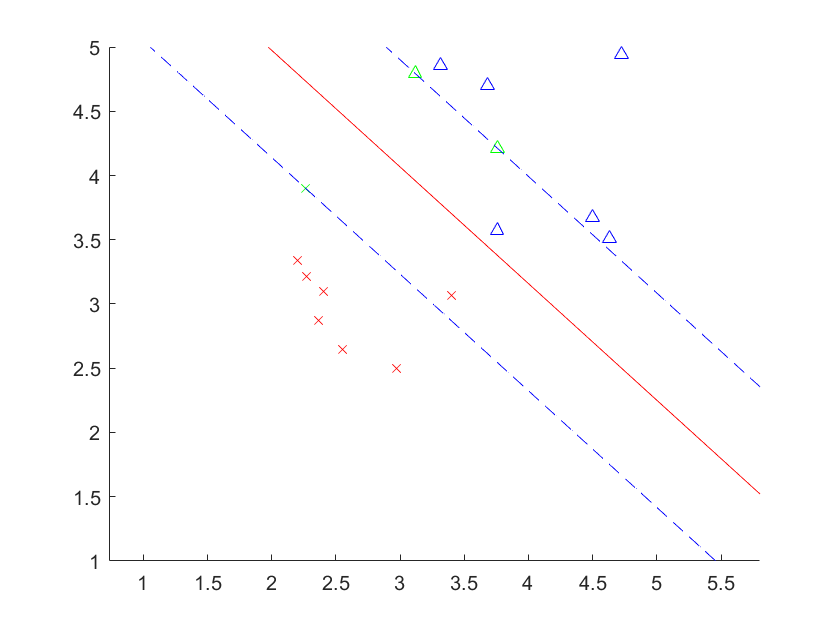

visualise(m,x,y,w,gamma,sv)

### Model 3: DrSVM

The Doubly Regularized SVM makes use of two regularization terms: one that is $L_1$ and one that is $L_2$.


$${\mathrm{min}}_u \;\frac{1}{2}u^T \left(\hat{Y} \left(\hat{X} {\left(C+\nu \;I\right)}^{-1} \hat{X^T } +ee^T \right)\hat{Y} +M\right)u-e^T u,\;\;\;u\ge 0$$


In general this problem is a nonconvex quadratic program, and so is not solved by an optimisation solver but, rather, a dedicated iterative procedure. The inputs for this function are: $x,y,\lambda \;,\nu \;$, followed by `max_iter`, the maximum number of iterations, and `lr`, the learning rate.

[w,gamma,sv] = dr_svm(x,y,1024)

w =    -0.7598
   -0.7141


gamma = -5.0499

sv =      4     6    11


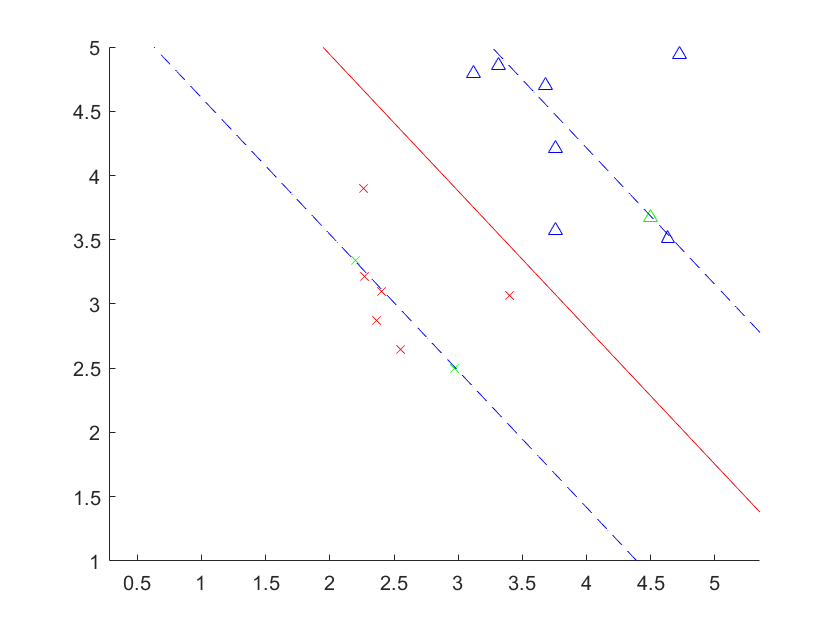

visualise(m,x,y,w,gamma,sv)

### Model 4: Robust SVM

To demonstrate the robust SVM, we will do the following:

- For each datapoint $x_i \;,\;i=1,\ldotp \ldotp \ldotp ,m$, we will choose a "radius of uncertainty" $r_{i\;} \in \left\lbrack 0,0\ldotp 2\right\rbrack$, to define for each datapoint an uncertainty set $U\left(r_i \right)={\bar{x} }_i +r_i B_2$. 

- We solve the corresponding optimisation problem


$${\mathrm{min}}_{w,\gamma ,\xi ,\mathrm{t1},\mathrm{t2}} \frac{1}{2}t_1^2 +\lambda \;t_2 \;\;\;\;\mathrm{subject}\;\mathrm{to}\;\;\;\;y_i \left({\bar{x_i } }^T w-\gamma \;\right)-y_i r_i \|\;w\|{\;}_2 +\xi {\;}_i \ge 1,i=1,\ldotp \ldotp \ldotp ,m,\;\;\|\;w{\|}_2 \le t_1 ,\;\;e^T \xi \le t_2 ,\;\;\xi \ge 0\;$$


- We then plot the solution and also include plots of the uncertainty regions for each datapoint. 

r = zeros(m,1);
for i=1:m
    r(i) = 0.2*rand(1);
end
[w, gamma, sv] = rob_svm(x,y,0.8,r)

w =    -1.1211
   -1.0405


gamma = -7.7168


sv =

     []



visualise_robust(m,x,y,w,gamma,sv,r)

It is worth noting that no support vectors are shown graphically for the robust method. The reason for this is because the robust approach does not use the raw data; instead it considers the worst case in each datapoint, in their uncertainty set; these are the points from which the support vectors are drawn. This process is inherent in the robust methodology.  

### Model Definitions

%%%%%%%%%%%%%%%%%%%%%%%
%       Std SVM
%%%%%%%%%%%%%%%%%%%%%%%


function [w,gamma,sv] = standard_svm(x,y,lambda)    
    %define parameters in desired form
    m = size(x,1); 
    Y = diag(y);
    X = x;
    e = ones(m,1);
    
    %define problem variables
    u = sdpvar(m,1);
    
    %objective function
    Obj = 0.5*u'*Y*(X*X')*Y'*u - e'*u;
    
    %constraints
    C = [e'*Y'*u == 0; u >= 0; u <= lambda*e];
    
    %solve
    optimize(C, Obj, sdpsettings('solver','mosek','verbose',0));
    
    %extract solution
    u = value(u);
    sv = [];
    for i =1:m
        if u(i) > 5*1e-8 && u(i) < lambda-5*(1e-8) %support vector, allowing for computer error
            sv = [sv i];
        end
    end
    if isempty(sv)
        error('No solution found. Please adjust tuning parameter. ')
    end
    w = X'*Y'*u;
    [~, I] = sort(u(sv),'ascend');
    new_sv = sv(I);
    ind = new_sv(ceil(end/2),2);
    gamma = -(1 - y(ind)*w'*x(ind,:)')/y(ind);
end 

%%%%%%%%%%%%%%%%%%%%%%%
%       L1-SVM
%%%%%%%%%%%%%%%%%%%%%%%

function [w,gamma,sv] = l1_svm(x,y,lambda)
    %define parameters in desired form
    m = size(x,1); 
    n = size(x,2);
    Y = diag(y);
    X = x;
    em = ones(m,1);
    en = ones(n,1);
    
    %define problem variables
    p = sdpvar(n,1);
    q = sdpvar(n,1);
    gamma = sdpvar(1);
    xi = sdpvar(m,1);    
    
    %objective function
    Obj = en'*(p+q) + lambda*em'*xi;
    
    %constraints
    C = [Y*(X*(p-q)-em*gamma)+xi >= em; p >= 0; q >= 0; xi >= 0];
    
    %solve
    optimize(C, Obj, sdpsettings('solver','mosek','verbose',0));
    
    %extract solution
    p = value(p);
    q = value(q);
    w = value(p-q);
    gamma = value(gamma);
    sv = [];
    for i =1:m
        marg = abs(w'*x(i,:)'-gamma);
        if marg >= 1-5*(1e-8) && marg <= 1+5*(1e-8) %support vector, allowing for computer error
            sv = [sv i];
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%
%       DR SVM
%%%%%%%%%%%%%%%%%%%%%%%

function [w,gamma,sv] = dr_svm(x,y,nu)
    %original parameters in desired form
    m = size(x,1); 
    n = size(x,2);
    Y = diag(y);
    X = x;
    e = ones(2*n+m,1);
    eh = [ones(m,1); zeros(2*n,1)];
    I = eye(2*n+m);
    
    %new problem-specific parameters
    Yhat = [Y zeros(m,2*n); zeros(2*n, m + 2*n)];
    Xhat = [zeros(m,m) X -X; zeros(2*n, m + 2*n)];
    C = [zeros(m, 2*n + m); zeros(2*n, m) eye(2*n)];
    V = inv(C+nu*I);
    Q = (Yhat*Xhat+I)*V*(Yhat*Xhat+I)' + Yhat*eh*eh'*Yhat';
    
    %optimisation problem and solution
    u = sdpvar(2*n+m,1);
    
    Obj = 0.5*u'*Q*u - eh'*u;    
    C = [u >= 0];
    
    optimize(C,Obj,sdpsettings('verbose',0,'solver','mosek'));
    
    u = value(u);
    
    sol = V*((Yhat*Xhat)'+I)*u;
    p = sol(m+1:m+n);
    q = sol(m+n+1:end);
    w = p - q;
    gamma = -eh'*Yhat*u;
    sv = [];
    for i =1:m
        marg = abs(w'*x(i,:)'-gamma);
        if marg >= 1-(1e-2) && marg <= 1+(1e-2) %support vector, allowing for computer error
            sv = [sv i];
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%
%     ROBUST SVM
%%%%%%%%%%%%%%%%%%%%%%%

function [w, gamma, sv] = rob_svm(x,y,lambda,r)
    %problem parameters
    m = size(x,1); 
    n = size(x,2);
    e = ones(m,1);
    
    %variables
    w = sdpvar(n,1);
    gamma = sdpvar(1);
    xi = sdpvar(m,1);
    t = sdpvar(2,1);
    
    %objective
    Obj = 0.5*t(1)^2 + lambda*t(2);
    
    %constraints: socp
    C = [norm(w,2) <= t(1); e'*xi <= t(2); xi >= 0];
    for i = 1:m
        C = [C; y(i)*(x(i,:)*w-gamma) - y(i)*r(i)*t(1) + xi(i) >= 1];
    end
    
    %solve
    optimize(C,Obj,sdpsettings('verbose',0,'solver','mosek'));
    
    w = value(w);
    gamma = value(gamma);
    sv = [];
    for i =1:m
        marg = abs(w'*x(i,:)'-gamma);
        if marg >= 1-(1e-8) && marg <= 1+(1e-8) %support vector, allowing for computer error
            sv = [sv i];
        end
    end
end

### Other Functions

function [] = visualise(m,x,y,w,gamma,sv)
    for i=1:m
        if y(i) == 1
            if isempty(sv(sv==i))
                scatter(x(i,1),x(i,2),'rx')
                hold on
            else
                scatter(x(i,1),x(i,2),'gx')
                hold on
            end
        else
            if isempty(sv(sv==i))
                scatter(x(i,1),x(i,2),'b^')
                hold on
            else
                scatter(x(i,1),x(i,2),'g^')
                hold on
            end
        end
    end
    fimplicit(@(X,Y) w(1)*X + w(2)*Y - gamma, 'r-')
    hold on
    fimplicit(@(X,Y) w(1)*X + w(2)*Y - gamma - 1, 'b--')
    hold on
    fimplicit(@(X,Y) w(1)*X + w(2)*Y - gamma + 1, 'b--')
    xlim([1,5])
    ylim([1,5])
    axis equal
    hold off
end

function [] = visualise_robust(m,x,y,w,gamma,sv,r)
    %also includes uncertainty regions
    thetas = linspace(-pi,pi,50);
    for i=1:m
        circle_x = r(i)*cos(thetas)+x(i,1);
        circle_y = r(i)*sin(thetas)+x(i,2);
        plot(circle_x,circle_y,'k--')
        hold on
    end
    visualise(m,x,y,w,gamma,sv)
    hold off
end